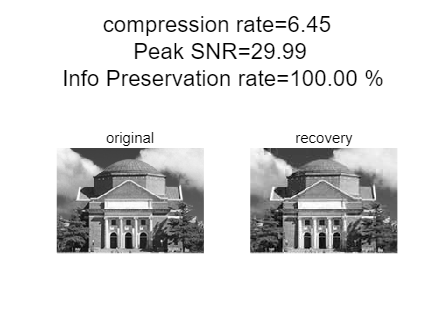

%steganography control
load hall.mat;
load JpegCoeff.mat;
info_raw_len=11451;
ori=hall_gray;
[H,W]=size(ori);
L=H*W;
B=L/64;
%type of steganography
tp=3;
% 0： space domain. 
if tp==0        
    info=randi([0,1],[1,L]);
    info_content=info;
% 1,2,3: freq domain
elseif tp==1
    info_valid_len=min(500,L);
    info_content=randi([0,1],[1,info_valid_len]);
    info=[info_content,zeros([1,L-info_valid_len])];
elseif tp==2 %now info could be less than L=H*W. We try to hide 1 bits in each block.
    info=randi([0,1],B*1,1);
    info=info_content;
elseif tp==3
    %we require the length of info be as same as number of blocks.
    %note that info takes value in {-1,1}.
    %we first create {-1,0}-->y= -2x-1 -->{-1,1}
    info_pre=randi([-1,0],1,B);
    info_content=-2.*info_pre-1;
end
%...JPEG process... 
[rec,cmpr,pksnr]=EnDeCoder_light(ori,info,tp);

% test info preservation rate
prsv=info_preserve(rec,info_content,tp);

%visualize
plt_compare(ori, rec, cmpr,prsv,pksnr);